## **Relief Feature Selection**

**Selection of significantly different features using machine learning feature selection method, Relief **

Filter style feature selection algorithm 

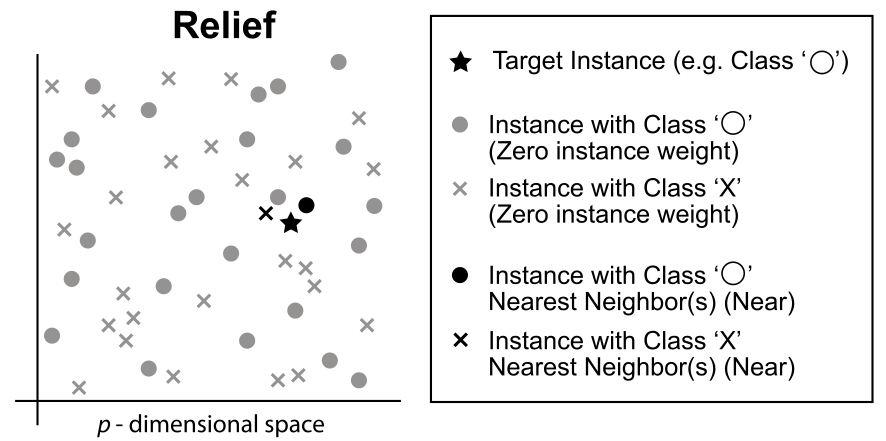

Kononenko, Igor (1994). *Machine Learning: ECML-94*. Lecture Notes in Computer Science. Vol. 784. Springer, Berlin, Heidelberg. pp. 171–182.

## Relief Feature Selection

Relief algorithm cycles through k random training samples, selected randomly without replacement, where k is a user-defined parameter optimized in the first part of this application through graphical analysis. 

In each cycle,   the ‘target’ instance is selected and for each feature (e.g. lipid) the score vector is updated based on feature value differences observed between the  target and neighboring instances. In each cycle, the distance  between the ‘target’ instance and all the other instances is calculated.  Relief identifies two nearest neighbor instances of the target; one with the same class, called the *nearest hit* (*H*) and the other with the opposite class, called the *nearest miss* (*M*). The last step of the cycle updates the weight of a feature  in *W (provided in the output)* if the feature value differs between the target instance  and either the nearest hit *H* or the nearest miss *M*. *(Urbanowicz, et al J Biomed Inf. 2018).* 

**Input file has to have a column called  ****Diagnosis**** that includes sample labels. Sample labels can be continuous variables (i.e. age) or discrete values (i.e. sex or diagnosis) and can be textual or numerical. **

**Input file:  **

        feature concentrations with column A sample IDs, column B called **Diagnosis** has information about sample groupings used for feature selection

Press enter. 

Following a short but highly rewarding wait plot of Weight v.s. K will appear

From this plot select K value with stable weight  and input in the box and press enter.

**Output file: **

    excel spreadsheet named Relieff**_***filename* of feature concentration input file and inluding following sheets:

        **Original Data** - return of the unchanged user input

        **Relieff Output** - list of feture names with Relieff weights. Features with values over 0.1 are strongly significatly different. Any features with positive weights show some level of contribution to separation of Diagnosis groups.

#### **Imputation of any missing data should be done prior to analysis but if there are any missing data remaining they will be imputed using 1/5 lowest value for the column (lipid) for the complete input (all Diagnosis groups)**

#### Press *File Input *and follow  prompts to select input file; after seeing the graph of weight changes with K, Enter K value in the box below.

 

clear all
[filenames1, filepath1]= uigetfile('*.xlsx', 'Select Data File');
%
warning('OFF')
opts = detectImportOptions(fullfile(filepath1,filenames1), 'ReadVariableNames', true,'PreserveVariableNames',true);
temp = readtable(fullfile(filepath1,filenames1),opts);
inputfile=temp;


**Optimize K value**

data=table2array(inputfile(:,3:end));

% put NaN to 1/5 of minimal measurement
data_control=data;
x=data;
for i=1:numel(data_control(1,:))
    for j=1:numel(data_control(:,1))       
        if isnan(data_control(j,i)) | isempty(data_control(j,i))
x(j,i)=min(data(:,i))/5;
        end
    end
end
y=inputfile.Diagnosis;

for i=1:200
k=i+1;
[idx,weights(k,:)] = relieff(x,y,k);
end
figure
%figure('Renderer', 'painters', 'Position', [10 10 1000 1000])

plot(weights);
xlabel('K');
ylabel('Weight');
title("Select optimal K value from the graph")


From graph select K value. This should be value where weight changes stabilize.

k=30;
k=30

[idx, weights]=relieff(x,y,k);

figure 
figure('Renderer', 'painters', 'Position', [10 10 1000 1000])

subplot(1,2,1);
barh(weights(idx(1:end)))
metid=inputfile.Properties.VariableNames(3:end);
%xtickangle(90) %idx(weights>0)
%yticklabels(metid(idx(1:end)));
title('Relieff determined feature weights - all');
subplot(1,2,2);
d=10;
barh(weights(idx(1:d)))
metid=inputfile.Properties.VariableNames(3:end);
%xtickangle(90) %idx(weights>0)
yticklabels(metid(idx(1:d)));
title('Relieff determined feature weights - top 10');

final_reportA=table(metid(idx(1:end))',weights(idx(1:end))' ,'VariableNames',...
    {'Lipids','Relieff Weights'});
filenames1=replace(filenames1,".csv","");

filenameoutput = strcat('Relieff_',string(filenames1),'.xlsx');
writetable(inputfile,filenameoutput,'FileType','spreadsheet','Sheet','Original Data');
writetable(final_reportA,filenameoutput,'FileType','spreadsheet','Sheet','Relieff weights');



**RELIEFF weights for each feature are saved in: **

filenameoutput

  Copyright, COMPLIMET.CA / AIDA  NRC/University of Ottawa  January  2024